## T7.GA.P01. 

a) (4p) Escribir una función Matlab para la integración con el método trapezoidal compuesto de una función  que se da mediante un conjunto de  puntos discretos. Los puntos no tienen que estar espaciados por igual. Para el nombre y los argumentos de la función utiliza: 

`I=IntPuntosTrap(x,y)`

donde los argumentos de entrada `x` e `y` son vectores con los valores de $x$ y los correspondientes valores de $y$, respectivamente. El argumento de salida `I` es el valor de la integral. 

b) En la tabla se indican las mediciones de la distribución de la velocidad de un fluido que circula por una tubería (flujo laminar). 

El caudal $Q$ (volumen de fluido por segundo) en la tubería puede calcularse mediante:


$$Q=\int_0^R 2\;\pi \;r\;v\;\textrm{dr}$$
    

donde $r=$ distancia al centro del tubo, $R=$ radio del tubo y $v=$ velocidad del fluido.

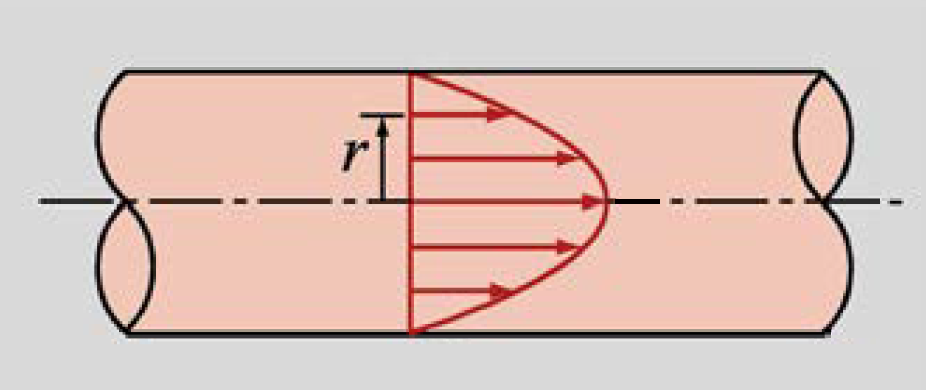

a) (2p) Ajusta un polinomio de 2º grado a los puntos , da la ecuación del polinomio, el error del ajuste y la desviación estándar. Representa los puntos junto con el polinomio. 

b) (1,5p) Calcula el caudal en $\frac{m^3 }{s}$integrando analíticamente el polinomio obtenido mediante una función de `Matlab`

c) (1,5p) Calcula el caudal en $\frac{m^3 }{s}$mediante la función del apartado a) sobre los puntos dados

d) (1p) Calcula el error relativo porcentual tomando como verdadero el valor obtenido en el apartado b)

1 in = 2.54 cm

**Respuesta:**

**a) Ajuste con polinomio de 2º grado**

clc, clear, clf
% datos del problema
r = 0 : 0.25 : 2; % in
v = [38.0 37.6 36.2 33.6 29.7 24.5 17.8 9.6 0]; % in / s

Pasamos de pulgadas a metros

r = r / (100/ 2.54);

Pasamos de $\frac{\textrm{in}}{s}$ a $\frac{m}{s}$

v = v / (100/ 2.54);

m = 2; % Ajuste de segundo grado

[p,Er,s] = PoliMulti(r,v,m);
fprintf('Polinomio de Interpolación: v = %.4f·r^2 + %.4f·r + %.4f', p(1), p(2), p(3))

Polinomio de Interpolación: v = -422.1972·r^2 + 2.6543·r + 0.9591

fprintf('Error del ajuse: %.6f', Er)

Error del ajuse: 0.000152

fprintf('Desviación Estándar: %.6f', s)

Desviación Estándar: 0.005036

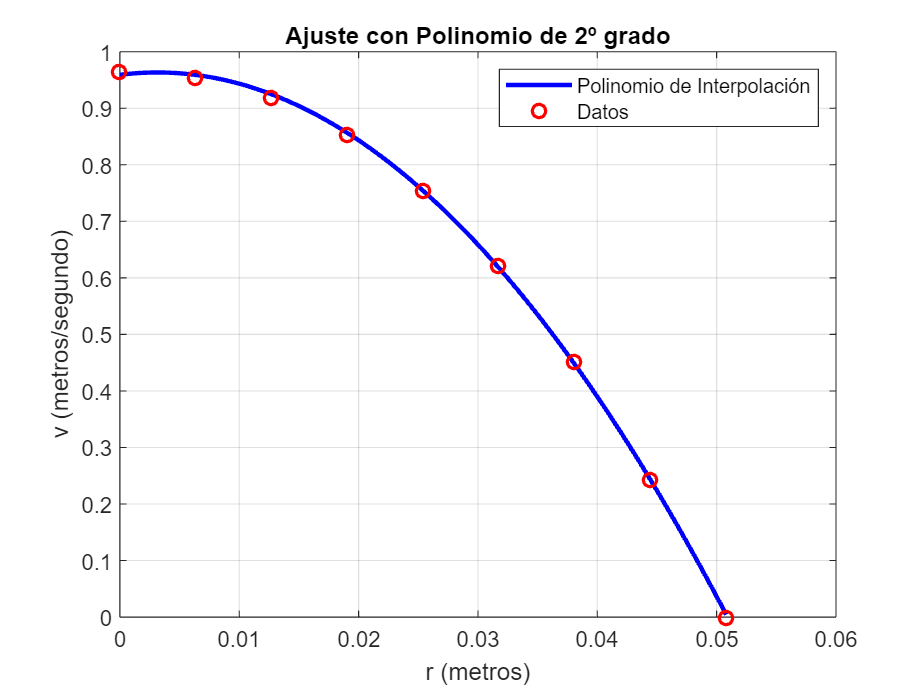


xp = linspace(min(r) ,max(r),100);
yp = (p(1)*xp.^2)+ p(2)*xp + p(3);

% gráfica
plot(xp,yp,'b','LineWidth',2)
hold on
plot(r,v,'or', 'LineWidth',1.5)
title('Ajuste con Polinomio de 2º grado')
xlabel('r (metros)')
ylabel('v (metros/segundo)')
legend('Polinomio de Interpolación', 'Datos', 'Location', 'northeast')
grid on
hold off

**b) Integral analitica con Matlab:**

% Polinomio Obtenido
fun = @(r) ((p(1).*r.^2) + (p(2).*r) + p(3));

% Intervalos de la integral
a = 0; 
b = max(r); % Radio del tubo = máxima distancia del centro del tubo

IntMatlab = integral(fun,a,b);

IntMatlab = 0.0337


% Cálculo del Caudal
QMat = 2*pi*IntMatlab;
fprintf('Caudal integrando analíticamente: %.4f m^3/s', QMat)

Caudal integrando analíticamente: 0.2117 m^3/s

**c) Integral con **`IntPuntosTrap`

% Cálculo de la integral
I = IntPuntosTrap(r, v);

I = 0.0335


% Cálculo del Caudal
Q = 2*pi*I;
fprintf('Caudal integrando con IntPuntosTrap: %.4f m^3/s', Q)

Caudal integrando con IntPuntosTrap: 0.2108 m^3/s

**d) Error relativo:**

Erelavito = abs((QMat - Q) / QMat) * 100;
fprintf('Error relavitvo porcentual: %.4f %%', Erelavito)

Error relavitvo porcentual: 0.4437 %